# MATH2089 Week 10

In previous weeks, we tested for the difference of means between two popultions. This week we'll examine the difference of means between an arbitrary number of populations. Suppose that each population is distributed $N(\mu_{i},\sigma)$, for $i = 1,\dots,k$—so that each population is Normally distributed with the same variance, but possibly different means. We want to test if all the population means are simultanesouly equal, i.e., if $\mu_{1}=\mu_{2}=\cdots=\mu_{K}$. 

We collect random samples from each population


$$X_{11},\dots,X_{1n_1}$$



$$X_{21},\dots,X_{2n_2}$$



$$\vdots$$


$X_{K1},\dots,X_{Kn_K}$,

and then compute their associated sample means $\overline{X}_{1},\dots,\overline{X}_{K}$, and sample variances $S^{2}_{1},\dots,S^{2}_{K}$. Let $n = \sum^{k}_{i = 1} n_{i}$. Now, each $S^{2}_{i}$ is an unbiased estimate for $\sigma^{2}$. Hence


$$\text{MS}_{\text{Er}} = \frac{\text{SS}_{\text{Er}}}{n - k} = \frac{1}{n - k}\sum^{K}_{i=1}(n_{i} - 1)S^{2}_{i} = \frac{1}{n - k}\sum^{K}_{i = 1}\sum^{n_{i}}_{j = 1}\left(X_{ij} - \overline{X}_{i}\right)^{2}$$


is also an unbiased estimate for $\sigma^{2}$—in fact, $\text{MS}_{\text{Er}}$ is a better estimator since it has lower variance. We know that $S^{2}_{i}\sim\chi^{2}_{n_{i} - 1}}$, which implies that $\text{SS}_{\text{Er}}\sim\chi^{2}_{n - k}$. The quantity $\text{MS}_{\text{Er}}$ computes the within-group variability.

If our hypothesised equality of means is true—$\mu_{i} = \mu$ for $1\leq i\leq k$—then$Y_{i} = \sqrt{n_{i}}\left(\overline{X}_{i} - \mu\right)\sim N(0,\sigma)$. Hence, $Y_{1},\dots,Y_{k}$ is an independent and identically distributed Normal random sample. The mean zero property of the $Y_{i}$ implies that 


$$\frac{1}{k - 1}\sum^{k}_{i - 1} Y^{2}_{i} = \frac{1}{k - 1}\sum^{k}_{i = 1} \sqrt{n_i}\left(\overline{X}_{i} - \mu\right)^{2}$$


is an unbiased estimator for $\sigma^{2}$. Note that under the hypothesised of equality of means, $\overline{\overline{X}}$ is an unbiased estimate for $\mu$. Hence, we can replace $\mu$ above with $\overline{\overline{X}}$ and still have an unbiased estimator for $\sigma^{2}$, i.e., 


$$\text{MS}_{\text{Tr}} = \frac{\text{SS}_{\text{Tr}}}{k-1} = \frac{1}{k - 1}\sum^{k}_{i = 1} \sqrt{n_i}\left(\overline{X}_{i} - \overline{\overline{X}}\right)^{2}$$


is an unbiased estimator for $\sigma^{2}$ if $\mu_{1}=\cdots=\mu_{k} = \mu$. This implies that $\text{SS}_{\text{Tr}}\sim\chi^{2}_{k - 1}$. Here $\text{MS}_{\text{Tr}}$ computes the between-group variability. 

Recall that $\text{MS}_{\text{Er}}$ is always an unbiased estimator for $\sigma^{2}$. However, $\text{MS}_{\text{Tr}}$ is only an unbiased estimator under the hypothesised equality of means. We can test the probability of equality using the $F$-test. In this case, our test statistic

$F = \frac{\text{MS}_{\text{Tr}} / (k - 1)}{\text{MS}_{\text{Er}} / (n - k)}\sim \mathbf{F}_{k - 1, n - k}$. 

If the hypothesis is true, then we would expect $\text{MS}_{\text{Er}}\approx\text{MS}_{\text{Tr}}$. If $F$ is unusually large, then the between group variance is larger than the within-group variance, indicating that our initial assumption is incorrect. 

## Question 1

We want to examine if the time of day affects download speeds. Consider the data set in `downloads.txt` which lists the time of day `period` and download speeds `dtime`. `MATLAB` will read `period` as a cell array, so we'll need to convert this into a categorical vector using the function `categorical()`. 

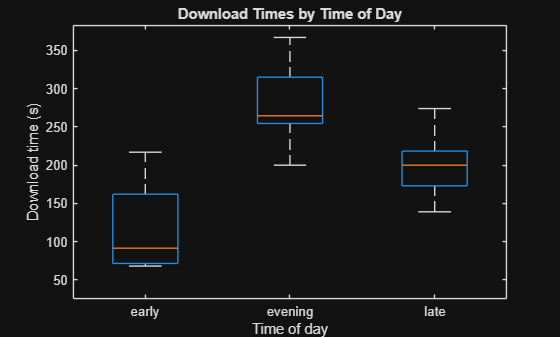

[dtime, period] = readvars("data/downloads.txt");

period = categorical(period); % convert cell array to categorical array

% Plot comparative boxplots
boxplot(dtime, period);
xlabel("Time of day");
ylabel("Download time (s)");
title("Download Times by Time of Day");

The comparative boxplots indicate that the time of day does appear to affect download speeds, with the early period having the fastest download speeds. 

Let's examine our model formally using `fitlm()`. We'll save our linear model to the object `downloadsMod`, which fits `dtime` as response and `period` as the regressor. 

downloadsMod = fitlm(period, dtime);

We make the following assumptions when fitting linear models with categorical regressors,

- The observations are independent within and between groups

- The random errors have mean zero

- The variance of reponses is equal between groups

- *(For hypothesis testing) *The random errors are Normally distributed

Criterion one can only be assessed through inspection of the study design. We see that the standard deviations are all within a factor of 2, and so passes the rule-of-thumb for the assumed equality of variances.

% help grpstats
[groupName, groupSize, groupMean, groupStD] = grpstats(dtime, period, {'gname', 'numel', 'mean', 'std'});
[string(groupName), groupStD] % print groupName as string (originally cell-type)

ans = 3×2 string array
    "early"      "57.4119"
    "evening"    "51.7713"
    "late"       "40.8761"


The quantile plot of residuals looks a little strange, however all the residuals seem to roughly follow a straight line, indicating the the residuals are Normally distributed. 

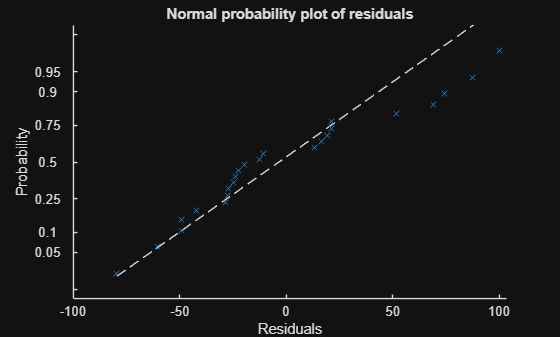

plotResiduals(downloadsMod, 'probability')

We'll formalise our conjecture, where the mean download times are different for different periods in the day, through a hypothesis test. Let $\mu_{\text{early}}, \mu_{\text{evening}}$ and $\mu_{\text{late}}$ be the respective *true* mean download time for the respective periods `early`, `evening`, and `late`. We assume that the mean download times are all equal and test to see if *at least one mean download time is different*. Note that this only requires that only one of $\mu_{\text{early}}, \mu_{\text{evening}}$ and $\mu_{\text{late}}$ are different from the others, and not that they are all different. Our hypotheses are


$$H_{0}: \mu_{\text{morning}} = \mu_{\text{evening}} = \mu_{\text{night}}$$


$H_{1}:$ not all means are equal. 

We utilise the statistic 

$F = \frac{\text{variance between treatments}}{\text{variance within treatments}} = \frac{MS_{\text{treatments}}}{MS_{\text{Error}}} = \frac{SS_{\text{treatments}} / (k - 1)}{SS_{\text{error}} / (n - 1)}$.

We know that $F\sim \mathbf{F}_{k - 1, n - k}$, where $\mathbf{F}_{k -1, n - k}$ is Fisher's $F$-distribution with degrees of freedom $k - 1$ and $n - k$. In this case, we have $k$ `= 3` groups and $n$ `= 24` observations, so that $F\sim\mathbf{F}_{2, 21}$.

[length(groupName), sum(groupSize)]

ans =      3    24


anova(downloadsMod)

ans = 2×5 table
               SumSq       DF    MeanSq      F        pValue  
             __________    __    ______    _____    __________

    x1       1.0564e+05     2     52818    20.72    1.0738e-05
    Error         53531    21    2549.1                       


Our observed test statistic is $f$ `= 20.7202`, whose associated $p$-value is $p = \mathbb{P}(F > f)\approx 10^{-5}$. This implies that we have very strong evidence against the null hypothesis, hence suggesting that average download times are affected by the time of day.

Suppose that we want to compute a *pairwise ANOVA test*, i.e., compare the means between two of the categories. We have the hypotheses


$$H_{0}: \mu_{i} = \mu_{j}$$


$H_{1}: \mu_{i}\neq \mu_{j}$.

The associated test statistic is

$T = \frac{\overline{X}_{i} - \overline{X}_{j}}{\sqrt{MS_{\text{Error}}\left(\frac{1}{n_{i}} + \frac{1}{n_{j}}\right)}} \sim t_{n - k}$. 

We apply the regular hypothesis test methods, only now we also have the adjustment $\alpha / K$ for the critical level, where $K = {k\choose 2}$ is the number of pairwise comparisons that we can make. 

[~, tbl, stats] = anova1(dtime, period, "off"); % perform one-way anova
[c, m, h, gnames] = multcompare(stats, "CriticalValueType", "bonferroni", "Display", "off");

output = array2table(c, 'VariableNames', {'Group A', 'Group B', 'CI lower', 'Estimate', 'CI upper', 'p value'});
output

output = 3×6 table
    Group A    Group B    CI lower    Estimate    CI upper     p value  
    _______    _______    ________    ________    ________    __________

       1          2       -228.17      -162.5     -96.831     6.6662e-06
       1          3       -148.29     -82.625     -16.956       0.010894
       2          3        14.206      79.875      145.54       0.014031


## Question 2

Let $\mu_{1}, \mu_{2}$, and $\mu_{3}$ respectively denote the true mean strength of the respective curing methods 1, 2,  and 3. Our null and alternative hypotheses are respectively


$$H_{0}: \mu_{1} = \mu_{2} = \mu_{3}$$



$$H_{a}: \text{at least one of the } \mu_{i} \text{ are different}$$


[method, batch, strength] = readvars("data/concrete.txt");

regressors = [method, batch];

concreteMod = fitlm(regressors, strength, 'CategoricalVars', [1, 2]);

anova(concreteMod)

ans = 3×5 table
             SumSq     DF    MeanSq      F         pValue  
             ______    __    ______    ______    __________

    x1       23.229     2    11.614    8.6946     0.0022784
    x2       86.793     9    9.6437    7.2193    0.00020215
    Error    24.045    18    1.3358                        


The ANOVA table provides the variation in strength according to the `method` (in row 1) and `batch `(in row 2). We are interested in the variation due to the `method`. The data of interest with respect to the hypotheses test we wish to perform is contained in the first row. Our test statistic is

$F = \frac{\text{Mean Square Treatment}}{\text{Mean Square Error}}$,

with an observed value of

$f \approx \frac{11.6143}{1.3358} \approx 8.6946$.

concreteModMethodOnly = fitlm(method, strength, 'CategoricalVars', 1);
anova(concreteModMethodOnly)

ans = 2×5 table
             SumSq     DF    MeanSq      F        pValue 
             ______    __    ______    ______    ________

    x1       23.229     2    11.614    2.8292    0.076642
    Error    110.84    27    4.1051                      
